close all; clear;


$$W_N =e^{-j\frac{2\pi }{N}}$$
 

N = 8;
W = zeros(N, N);
for a = 0:1:N-1
    for b = 0:1:N-1
        W(a+1,b+1) = exp(-1j*2*pi*a*b/N);
    end
end

m = N/2;
W = exp(-2*pi*sqrt(-1)/N).^(0:m-1)'

W =    1.0000 + 0.0000i
   0.7071 + 0.7071i
   0.0000 + 1.0000i
  -0.7071 + 0.7071i



N1 = 4; m1 = N1/2;
A = [1 2 3 4; 5 6 7 8; 8 7 6 5; 4 3 2 1]

A =      1     2     3     4
     5     6     7     8
     8     7     6     5
     4     3     2     1


A(2,1)

ans = 5

A(:,2)

ans =      2
     6
     7
     3


A(1:m1,1:2:N1-1)

ans =      1     3
     5     7



C = [1 2 3; 2 3 4; 5 6 7]

C =      1     2     3
     2     3     4
     5     6     7


B = [3; 7; 1]

B =      3
     7
     1


C*B

ans =     20
    31
    64



x = (0:15)';
v = bitrevorder(x);
x_bin = dec2bin(x);
v_bin = dec2bin(v);
T = table(x,x_bin,v,v_bin)

T = 16×4 table
    x     x_bin    v     v_bin
    __    _____    __    _____

     0    0000      0    0000 
     1    0001      8    1000 
     2    0010      4    0100 
     3    0011     12    1100 
     4    0100      2    0010 
     5    0101     10    1010 
     6    0110      6    0110 
     7    0111     14    1110 
     8    1000      1    0001 
     9    1001      9    1001 
    10    1010      5    0101 
    11    1011     13    1101 
    12    1100      3    0011 
    13    1101     11    1011 
    14    1110      7    0111 
    15    1111     15    1111 



a = mod(4,2)

a = 0

b = mod(5,2)

b = 1


N = 5;
if(mod(N,2))
    c = 2
    d = 1
else
    c = 3
    d = 3
end

c = 2

d = 1


h3 = [1 2];
h4 = [-1 -2];
if (h3 == -h4) & (h4==[-1 -2])
    a = 1
    aass = 1
end

a = 1

aass = 1


h = [1 2 3 4 5]

h =      1     2     3     4     5


N = length(h)

N = 5

h1 = h(1:1:((N-1)/2))

h1 =      1     2


h2 = h(N:-1:((N+3)/2))

h2 =      5     4


h = reshape(h,1,N)

h =      1     2     3     4     5



M = 5

M = 5

x = [1 1 1 1 1 1 1 1 1 1]

x =      1     1     1     1     1     1     1     1     1     1


x = [zeros(M,1);x(:)]

x =      0
     0
     0
     0
     0
     1
     1
     1
     1
     1



x = ones(1, 10)

x =      1     1     1     1     1     1     1     1     1     1


m = 10; M = 100; L = 1; g = 9.81;
KP = 1; KI = 1; KD = 1;
syms x;
eqn = M*L*x^3 - KD*x^2 - ((M+m)*g+KP)*x - KI == 0;
s = solve(eqn, x);
digits(6)
vpa(s) 

$$ans = \left(\begin{array}{c} -0.000925841\\ -3.28103\\ 3.29195 \end{array}\right)$$

close all; clear;
x = [1 2 3 4 5 6 7 8];
X = fft(x); N = length(X);
W = zeros(1,N);
for n = 1:1:N
    W(n) = X(1:1:N)*exp(-1*sqrt(-1)*2*pi*(n-1).*(0:1:N-1)'/N);
end
W = W./N

W =    1.0000 + 0.0000i   8.0000 + 0.0000i   7.0000 + 0.0000i   6.0000 - 0.0000i   5.0000 + 0.0000i   4.0000 + 0.0000i   3.0000 + 0.0000i   2.0000 - 0.0000i



(0:1:N-1)'

ans =      0
     1
     2
     3
     4
     5
     6
     7


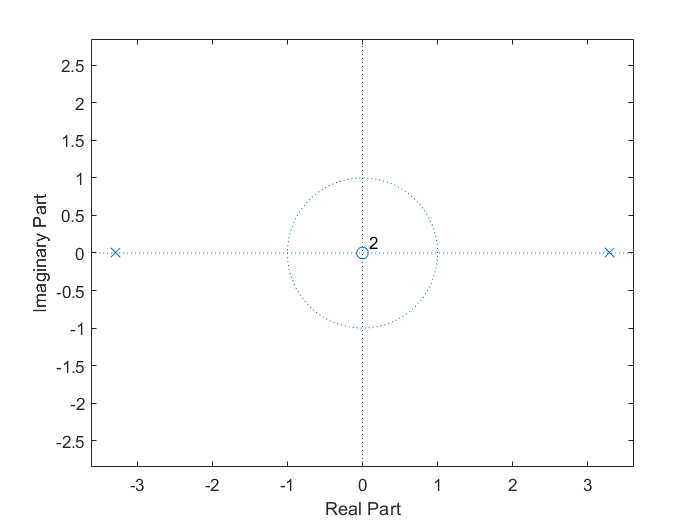

close all; clear;
m = 10; M = 100; L = 1; g = 9.81;
b = [-1/(M*L)]; % -0.01
a = [1 0 -(M+m)*g/(M*L)]; % [1 0 -10.7910]
figure; zplane(b,a);

[zero,pole,k] = tf2zp(b,a)


zero =

  0×1 empty double column vector



pole =     3.2850
   -3.2850


k = -0.0100

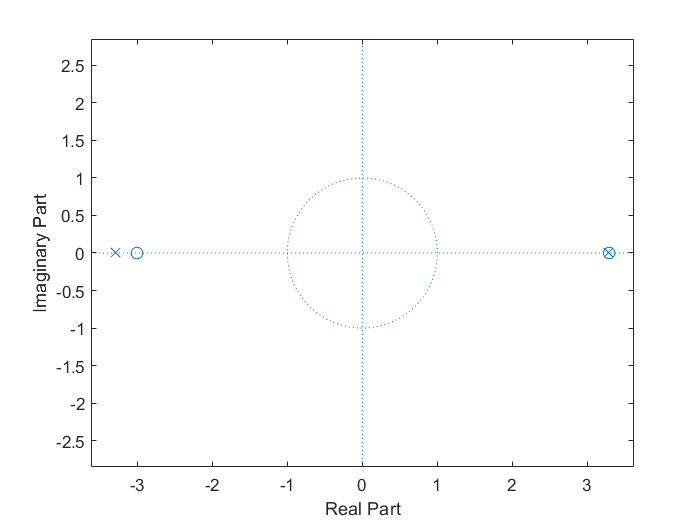


b_pid = [1 -0.285 -9.885];
% b_pid = [-1 3.285 0];
a_pid = [1];
b_all = conv(b_pid, b);
a_all = conv(a_pid, a);
figure; zplane(b_all,a_all);

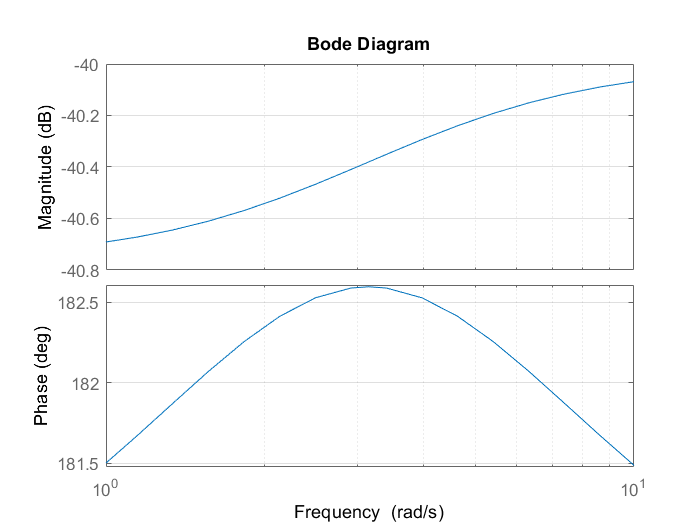


sys = tf(b_all, a_all);
figure; bode(sys); grid on;

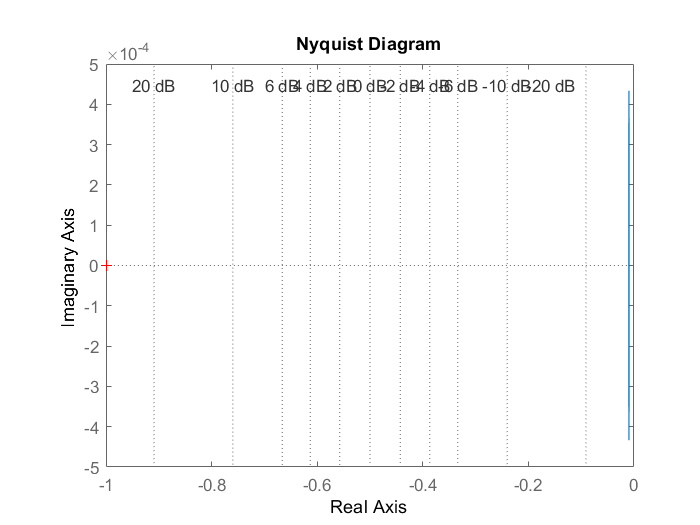

figure; nyquist(sys); grid on;

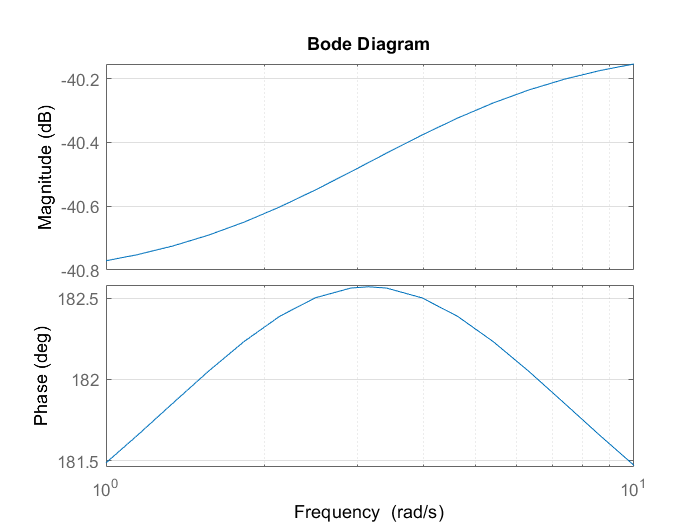


T_sys = feedback(sys,1,+1);
figure; bode(T_sys); grid on;

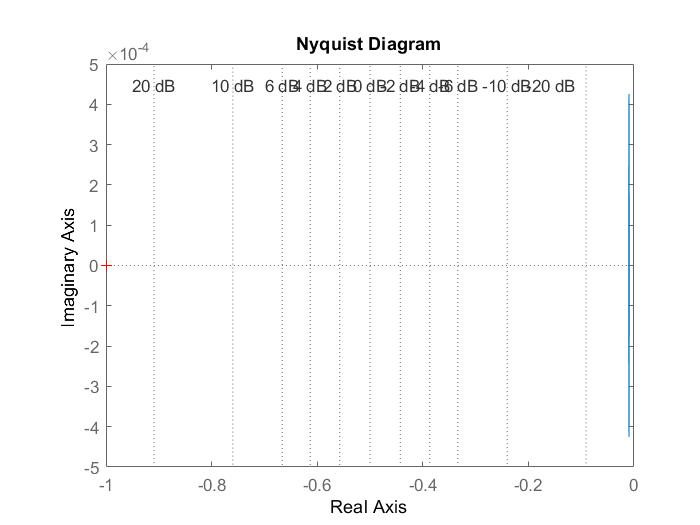

figure; nyquist(T_sys); grid on;

close all; clear;
a = [1 2 3 4; 5 6 7 8];
a(1,2)

ans = 2

length(a)

ans = 4


nm = [1 3 3 1 3 5 13 1] 

nm =      1     3     3     1     3     5    13     1


dn = [3 0 1 0 7 13 2 2]

dn =      3     0     1     0     7    13     2     2


[ss,gn] = tf2sos(nm,dn)

ss =     1.0000    0.0792         0    1.0000    1.0686         0
    1.0000    3.6662    4.0127    1.0000    0.0715    0.1599
    1.0000   -1.8579    1.6563    1.0000   -2.2743    2.2148
    1.0000    1.1125    1.8992    1.0000    1.1342    1.7614


gn = 0.3333


x = [1 2 3 4 5 6 7 8]

x =      1     2     3     4     5     6     7     8


X = fft(x); N = length(X)

N = 8

u = zeros(6,1); u(2) = 2;
u

u =      0
     2
     0
     0
     0
     0


ans =      1     2     3
